# Asservissement du robot EV3 en position

## Données moteur lego

%Résistance
R = 6.833; 
%Bloc Couple - vitesse de rotation
J = 1.5e-3;     
f = 7.27e-4;
% Couple résistant du moteur
Cr = 0;  
%Constante mécanique du moteur
Km = 0.305; 
%Constante électrique du moteur 
Ke = 0.460;
%Gain capteur vitesse de rotation
K = 0.5;

%Tension d'entrée
U = 5;      %Tension d'entrée

%Inductance non utilisée.
L = 4.94e-3;  

## Schéma d'asservissement continu

### Schéma réel

sim("Asservissement_Robot.slx")

ans =   Simulink.SimulationOutput:

                      X: [1x1 timeseries] 
                    X_c: [1x1 timeseries] 
                   tout: [135x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


### Résultats

%Consigne/sortie
hold on

p1 = plot(out.X_c)

p1 =   Stair with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×135 double]
              YData: [1×135 double]

  Show all properties


p2 = plot(out.X)

p2 =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×135 double]
              YData: [1×135 double]
              ZData: [1×0 double]

  Show all properties


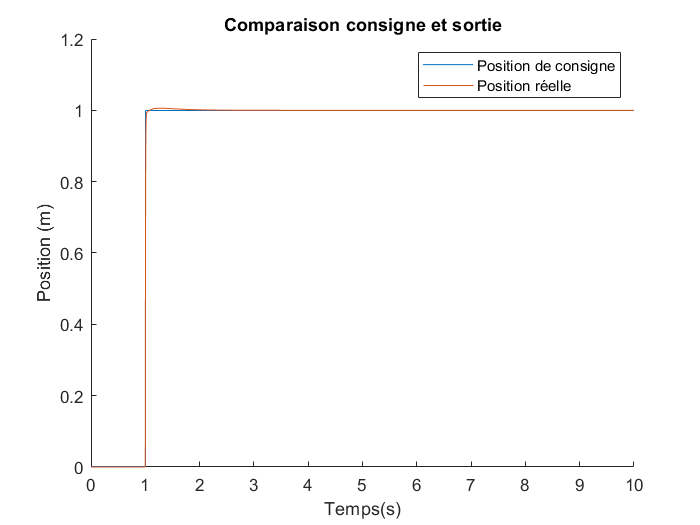


legend([p1,p2],'Position de consigne', 'Position réelle')
title('Comparaison consigne et sortie')
xlabel('Temps(s)')
ylabel('Position (m)')

hold off